# Simulation Tests

Goal is to simulate a wave spectrum and then verify the functions in the wave.m library.

## 1 Simulate the wave spectrum E(f,theta)

waveLibrary = waveLibrary;
plotLibrary = plotLibrary;

### 1.1 1D Wave spectrum E(omega)

numberOfFrequencyBins = 24;
numberOfDirectionBins = 30;

% f = linspace(0.01,1,numberOfFrequencyBins)';

f = zeros(numberOfFrequencyBins,1);
        f(1) = 0.03453;
        for i=2:length(f)
            f(i) = f(i-1)*1.1;
        end

test_kmin = sqrt(2*pi * min(f))/9.81

test_kmin = 0.0475

test_kmax = sqrt(2*pi * max(f))/9.81

test_kmax = 0.1421

Hs = 5;      % Significant wave height
T0 = 10;        % Significant wave period, this dictates the peak frequency, f_peak and w0
mean_wave_direction_degrees = 20;
gammaWaveValueInput = 1.3715; % Some factor between 1 and 5

% Now calculate the direction bins such that the mean wave direction is at
% the center. This is necessary to ensure the corrrect directional
% distribution function calculation. Essentially this sets the mean wave
% direction as the zero point around which the wave is then distributed.
% See figure6.7 in Holthuijsen and Figure 6.9
max_degree_bin = 352.5; % ERA5 maximum
min_degree_bin = 7.5;
bin_spacing = (max_degree_bin-min_degree_bin)/numberOfDirectionBins; % Calculate the grid spacing
direction_bins_degrees = linspace(mean_wave_direction_degrees-(bin_spacing*numberOfDirectionBins/2), ...
                                    mean_wave_direction_degrees+(bin_spacing*numberOfDirectionBins/2) ...
                                    ,numberOfDirectionBins)

direction_bins_degrees =  -152.5000 -140.6034 -128.7069 -116.8103 -104.9138  -93.0172  -81.1207  -69.2241  -57.3276  -45.4310  -33.5345  -21.6379   -9.7414    2.1552   14.0517   25.9483   37.8448   49.7414   61.6379   73.5345   85.4310   97.3276  109.2241  121.1207  133.0172  144.9138  156.8103  168.7069  180.6034  192.5000


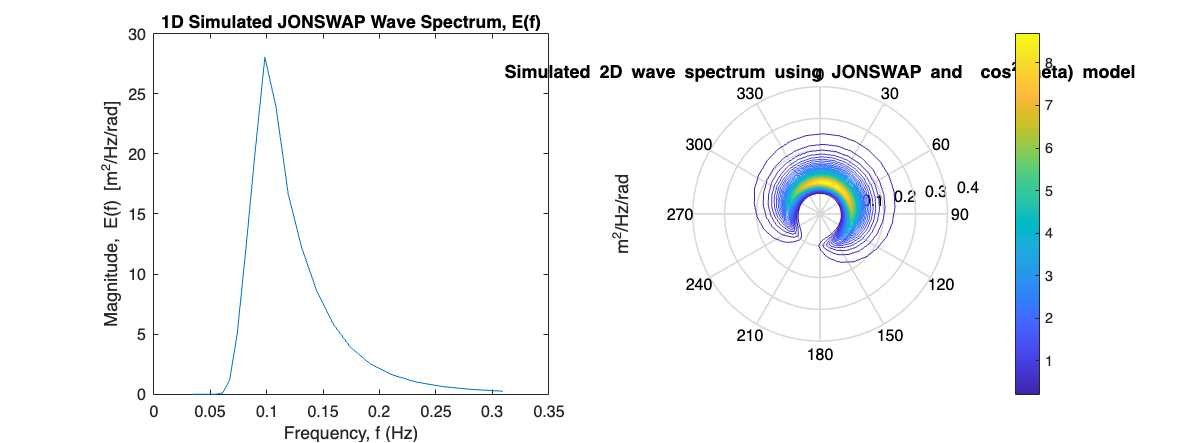

% direction_bins_degrees = mod(direction_bins_degrees, 360) % Wrap to ensure all values are within [0, 360] range
[S_1D_f, S_2D_cosm_rad] = waveLibrary.simulateWaveSpectrum(Hs,gammaWaveValueInput,f,T0, mean_wave_direction_degrees, direction_bins_degrees, 0, 'JONSWAP');
plotWaveSpectra = true;

if plotWaveSpectra
    figure('Position', [0, 0, 800, 300]);
    subplot(1,2,1); plotLibrary.waveSpectrum1D(S_1D_f,f,"1D Simulated JONSWAP Wave Spectrum, E(f)");
        
    subplot(1,2,2); 
    plotLibrary.waveSpectrum2D(1, abs(S_2D_cosm_rad)', f, direction_bins_degrees, 1, "Simulated 2D wave spectrum using JONSWAP and  cos^2(theta) model");
end

#### 1.1.1 Test that the 2D spectrum and 1D spectrum are correct

%% ------------------------------------------------------------------------------------------------------------------------
% Calc parameters of 1D to check that it matches the input
m0_1D = trapz(f,S_1D_f,1);
Hs_1D = 4 * sqrt(m0_1D)

Hs_1D = 5

m1_1D = trapz(f,S_1D_f .* f.^1,1);
Tm_1D = (m1_1D/m0_1D)^(-1) % [Holthuijsen Eq.5]

Tm_1D = 8.0988

% Calc parameters of 2D to check that it matches the input
[Hs_derived,Tm_derived,direction_derived,total_variance_or_energy_derived] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,S_2D_cosm_rad)

Hs_derived = 5

Tm_derived = 8.0988

direction_derived = 20.0000

total_variance_or_energy_derived = 691.2412

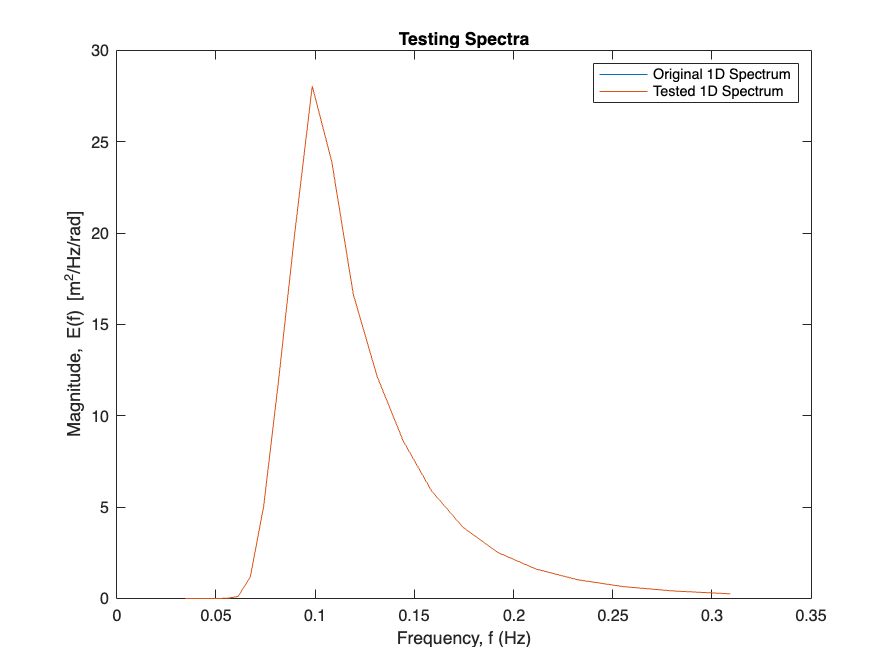

% Make that when we integrate the 2D spectrum that it returns the 1D
% spectrum
test = trapz(direction_bins_degrees.* pi/180,S_2D_cosm_rad,2);
figure;
    plotLibrary.waveSpectrum1D(S_1D_f,f,"Testing Spectra");
    hold on;
    plotLibrary.waveSpectrum1D(test,f,"Testing Spectra");
    hold off;
    legend("Original 1D Spectrum","Tested 1D Spectrum");

%%------------------------------------------------------------------------------------------------------------------------------------

f_new = linspace(0.01, 1, 128);
 % theta_new = linspace(0,365,128);
theta_new = linspace(mean_wave_direction_degrees-(bin_spacing*numberOfDirectionBins/2), ...
                                    mean_wave_direction_degrees+(bin_spacing*numberOfDirectionBins/2) ...
                                    ,128)

S_2D_cosm_rad(isnan(S_2D_cosm_rad))=0;
[f_temp, theta_temp] = meshgrid(f,direction_bins_degrees);
F = scatteredInterpolant(f_temp(:) , theta_temp(:) , S_2D_cosm_rad(:), 'linear','none');
[interp_f, interp_theta] = meshgrid(f_new,theta_new);
interp_S = F(interp_f,interp_theta);
interp_S(isnan(interp_S))=0;

plotLibrary.waveSpectrum2D(1, abs(interp_S)', f_new, theta_new, 4, "Wave Spectrum after conversion E(Kx,ky) --> E(f,theta)");

## 2 Test Characteristics calculation

This is to test that the script for calculating the wave parameters is correct.

[final_Hs_derived,final_Tm_derived,final_direction_derived,final_total_variance_or_energy_derived] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,S_2D_cosm_rad)

## 3 Test Wave Number Spectrum Calculation

### 3.1 Generate wave number spectrum generation: E(f,theta) --> E(kx,ky) --> E(f,theta)

w = f.*(2*pi);
k = (w).^2 ./ 9.81;
[E_kx_ky, Jacobian, kx_matrix,ky_matrix] = waveLibrary.waveNumberSpectrum(S_2D_cosm_rad,w,k, direction_bins_degrees);

[wave_spectrum,Jacobian] = waveLibrary.waveSpectrum(E_kx_ky, w, k);

% Plot the spectra
figure('Position', [0, 0, 1200, 300]);
    subplot(1,3,1); plotLibrary.waveSpectrum2D(1, abs(S_2D_cosm_rad)', f, direction_bins_degrees, 1, "Simulated 2D wave spectrum E(f,theta)");

    subplot(1,3,2); plotLibrary.waveNumberSpectrum(E_kx_ky, kx_matrix, ky_matrix, "Wave number spectrum, E(kx,ky)");
    
    subplot(1,3,3); 
    plotLibrary.waveSpectrum2D(1, abs(wave_spectrum)', f, direction_bins_degrees, 1, "Wave Spectrum after conversion E9Kx,ky) --> E(f,theta)");

### 3.2 Test

% Show that the wave spectrum, calculated from the wave number spectrum, looks like the original wave spectrum    
figure('Position', [0, 0, 800, 300]);
    subplot(1,2,1);
    contour(f,direction_bins_degrees, S_2D_cosm_rad');
    xlabel("Frequency"); ylabel('Direction [degrees]');title("Final 2-D Wave Spectrum, E(f,theta)", "calculated from E(k)"); c = colorbar();c.Label.String = '[m^2 s / rad]';
    hold on;
    contour(f,direction_bins_degrees, wave_spectrum');
    xlabel("Frequency"); ylabel('Direction [degrees]');title("Final 2-D Wave Spectrum, E(f,theta)", "calculated from E(k)"); c = colorbar();c.Label.String = '[m^2 s / rad]';
    legend("Original 2D Spectrum","Tested 2D Spectrum (E(k)-->E(f,theta))");
    subplot(1,2,2);
    plotLibrary.waveSpectrum2D(1, abs(S_2D_cosm_rad)', f, direction_bins_degrees, 1, "Simulated 2D wave spectrum E(f,theta)");
    hold on;
    plotLibrary.waveSpectrum2D(1, abs(wave_spectrum)', f, direction_bins_degrees, 1, "Simulated 2D wave spectrum E(f,theta)");
    hold off;

    % legend("Original 2D Spectrum","Tested 2D Spectrum (E(k)-->E(f,theta))");

% COMPARE the parameter values
[original_Hs,original_Tm,original_direction,original_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,S_2D_cosm_rad)

original_Hs = 5

original_Tm = 8.0988

original_direction = 20.0000

original_tot_variance = 691.2412

[test_Hs,test_Tm,test_direction,test_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,wave_spectrum)

test_Hs = 5

test_Tm = 8.0988

test_direction = 20.0000

test_tot_variance = 691.2412

## 4 Test Angle Adjustment

### 4.1 Apply adjustment to wave spectrum

sar_azimuth_to_north_angle = 15;
adjusted_direction_bins_degrees = direction_bins_degrees + sar_azimuth_to_north_angle;

%% COMPARE spectra with angle adjustment
figure('Position', [0, 0, 1200, 300]);
subplot(1,3,1); plotLibrary.waveSpectrumAdjustedToSAR(wave_spectrum', f, direction_bins_degrees, 1, "Original 2-D Wave Spectrum, E(f,theta)");
subplot(1,3,2); plotLibrary.waveSpectrumAdjustedToSAR(wave_spectrum', f, adjusted_direction_bins_degrees, 1, "Adjusted to SAR scene geometry 2-D Wave Spectrum, E(f,theta)");
subplot(1,3,3);
    plotLibrary.waveSpectrumAdjustedToSAR(wave_spectrum', f, adjusted_direction_bins_degrees, 1, "");
    hold on;
    plotLibrary.waveSpectrumAdjustedToSAR(wave_spectrum', f, direction_bins_degrees, 1, "Comparison of original vs adjusted spectrum");
% COMPARE the parameter values
[original_Hs,original_Tm,original_direction,original_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,S_2D_cosm_rad)
[adjustement_test_Hs,adjustement_test_Tm,adjustement_test_direction,adjustement_test_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(adjusted_direction_bins_degrees.* pi/180,f,wave_spectrum)
if(round(abs(original_direction-adjustement_test_direction),5) == sar_azimuth_to_north_angle || ((180-original_direction)+adjustement_test_direction) == sar_azimuth_to_north_angle)
    disp("Test passed")
else
    disp("Test failed")
end

### 4.2 Test with wave number transform

[adjusted_E_kx_ky, adjusted_Jacobian,adjusted_kx_matrix,adjusted_ky_matrix] = waveLibrary.waveNumberSpectrum(S_2D_cosm_rad,w,k, adjusted_direction_bins_degrees);
[adjusted_wave_spectrum, adjusted_Jacobian] = waveLibrary.waveSpectrum(adjusted_E_kx_ky, w, k);

figure('Position', [0, 0, 1200, 300]);
subplot(1,3,1); plotLibrary.waveNumberSpectrum(E_kx_ky, kx_matrix, ky_matrix, "Original Wave number spectrum, E(kx,ky)");

subplot(1,3,2); plotLibrary.waveNumberSpectrum(adjusted_E_kx_ky, adjusted_kx_matrix, adjusted_ky_matrix, "Adjusted E(kx,ky)");
    
subplot(1,3,3); 
    plotLibrary.waveNumberSpectrum(E_kx_ky, kx_matrix, ky_matrix, "");
    hold on;
    plotLibrary.waveNumberSpectrum(adjusted_E_kx_ky, adjusted_kx_matrix, adjusted_ky_matrix, "Comparison Test");
    hold off;
% COMPARE the parameter values
[original_Hs,original_Tm,original_direction,original_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,S_2D_cosm_rad)
[adjustement_test_Hs,adjustement_test_Tm,adjustement_test_direction,adjustement_test_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(adjusted_direction_bins_degrees.* pi/180,f,adjusted_wave_spectrum)

[adjustement_rem_test_Hs,adjustement_rem_test_Tm,adjustement_rem_test_direction,adjustement_rem_test_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,adjusted_wave_spectrum)

if(round(abs(original_direction-adjustement_test_direction),5) == sar_azimuth_to_north_angle || ((180-original_direction)+adjustement_test_direction) == sar_azimuth_to_north_angle)
    disp("Test 1 passed: angle adjustment correctly applied")
else
    disp("Test 1 failed")
end
if(round(adjustement_rem_test_direction,5) == round(original_direction,5))
    disp("Test 2 passed: angle adjustment successfully removed")
else
    disp("Test 2 failed")
end

There is an issue with subtracting the angle from the adjusted bins and using it to readjust the spectrum back to the original wave spectrum orientation. The issue is that the adjusted_rem_direction_bins_degrees are a very small factor off of the original direction_bins_degrees. This could lead to inaccuracies in the final calculated spectrum. However, to then use the original bins once interpolation is added to the process, the original bins will need to be interpolated too.

adjusted_rem_direction_bins_degrees = adjusted_direction_bins_degrees - sar_azimuth_to_north_angle;

difference = direction_bins_degrees - adjusted_rem_direction_bins_degrees

## 5 Test Interpolation

sar_sub_transect_size = 128;
sar_dx_range = 15;
sar_dy_azimuth = 15;
gravity =9.81;

%------------------------------------------------
w = f.*(2*pi);
k = (w).^2 ./ 9.81;
% Calculate wave phase speed 
cw = w./k;
% Calculate group wave phase speed 
cg = 0.5 .* cw;
R_k = k;
E_w_theta_rad = S_2D_cosm_rad ./(2 * pi);
E_k_theta_rad = E_w_theta_rad .* cg;
[test_interp_E_kx_ky, X,Y] = polar_surface(R_k, direction_bins_degrees.*(pi/180), E_k_theta_rad);
%------------------------------------------------
[Th,R_k_out,E_k_theta_out] = cart2pol(X,Y,test_interp_E_kx_ky);
w_out = sqrt(R_k_out.*9.81);
cw_out = w_out./R_k_out;
cg_out = 0.5 .* cw_out;
E_f_theta_out = E_k_theta_out .* (2*pi) ./cg_out;
f_out = w_out./(2*pi);

figure; contour(f_out,Th,E_f_theta_out);
colorbar;
f_out_2 = linspace(min(f_out(:)),1,100);
Th_2 = linspace(min(Th(:)),max(Th(:)),100);
[test_interp_Hs,test_interp_Tm,test_interp_direction,test_interp_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(Th_2,f_out_2,E_f_theta_out)



%------------------------------------------------
[interp_E_kx_ky,interp_kx_matrix,interp_ky_matrix,interp_k_matrix] = waveLibrary.interpolateWaveNumberSpectrum(sar_sub_transect_size,sar_dx_range, sar_dy_azimuth, E_kx_ky, kx_matrix, ky_matrix);
figure('Position', [200, 200, 800, 300]);
subplot(1,2,1); plotLibrary.waveNumberSpectrum(E_kx_ky, kx_matrix, ky_matrix, "Original Wave Number Spectrum");
subplot(1,2,2); plotLibrary.waveNumberSpectrum(interp_E_kx_ky, interp_kx_matrix(1,:), interp_ky_matrix(:,1), "Interpolated Wave Number Spectrum")
interp_w_matrix = sqrt(gravity .* interp_k_matrix);
interp_f_matrix = interp_w_matrix./(2*pi); % THIS COULD BE THE ISSUE
interp_f =  linspace(min(interp_f_matrix(:)),max(interp_f_matrix(:)),sar_sub_transect_size); % THIS COULD BE THE ISSUE
interp_direction_bins = linspace(min(direction_bins_degrees),max(direction_bins_degrees),sar_sub_transect_size);
% interp_direction_bins = atan(interp_ky_matrix./interp_kx_matrix) .* 180/pi;

[interp_wave_spectrum, interp_Jacobian] = waveLibrary.waveSpectrum(interp_E_kx_ky, interp_w_matrix, interp_k_matrix);
% 
% % TESTING
% interp_k = sqrt(interp_kx_matrix(1,:).^2 + (interp_ky_matrix(:,1).^2)')
% interp_w = sqrt(gravity .* interp_k);
% interp_f_2 = interp_w./(2*pi);
% [interp_wave_spectrum_2, interp_Jacobian_2] = waveLibrary.waveSpectrum(interp_E_kx_ky, interp_w, interp_k);

% figure('Position', [0, 0, 800, 800]);
% subplot(2,2,1); plotLibrary.waveSpectrum2D(1, abs(wave_spectrum)', f, direction_bins_degrees, 1, "Original 2-D Wave Spectrum, E(f,theta)");
% subplot(2,2,2); plotLibrary.waveSpectrum2D(1, abs(interp_wave_spectrum_2)', interp_f_2, interp_direction_bins, 1, "Interpolated 2-D Wave Spectrum, E(f,theta)");
% subplot(2,2,3); plotLibrary.waveSpectrum2D(0, abs(wave_spectrum)', f, direction_bins_degrees, 1, "Original 2-D Wave Spectrum, E(f,theta)");
% subplot(2,2,4); plotLibrary.waveSpectrum2D(0, abs(interp_wave_spectrum_2)', interp_f_2, interp_direction_bins, 1, "Interpolated 2-D Wave Spectrum, E(f,theta)");


figure('Position', [0, 0, 800, 800]);
subplot(2,2,1); plotLibrary.waveSpectrum2D(1, abs(wave_spectrum)', f, direction_bins_degrees, 1, "Original 2-D Wave Spectrum, E(f,theta)");
subplot(2,2,2); 
plotLibrary.waveSpectrum2D(1, abs(interp_wave_spectrum), interp_f, interp_direction_bins', 1, "Interpolated 2-D Wave Spectrum, E(f,theta)");
subplot(2,2,3); plotLibrary.waveSpectrum2D(0, abs(wave_spectrum)', f, direction_bins_degrees, 1, "Original 2-D Wave Spectrum, E(f,theta)");
subplot(2,2,4); plotLibrary.waveSpectrum2D(0, abs(interp_wave_spectrum)', interp_f, interp_direction_bins, 1, "Interpolated 2-D Wave Spectrum, E(f,theta)");




[original_Hs,original_Tm,original_direction,original_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(direction_bins_degrees.* pi/180,f,S_2D_cosm_rad)

[interp_test_Hs,interp_test_test_Tm,interp_test_test_direction,interp_test_test_tot_variance] = ...
    waveLibrary.calculateSpectrumCharacteristics(interp_direction_bins.* pi/180,interp_f,interp_wave_spectrum)

%------------------------------------------------------------------
percentage_difference_Hs = ((original_Hs-interp_test_Hs)/original_Hs) *100
percentage_difference_Tm = ((original_Tm-interp_test_test_Tm)/original_Tm) *100
percentage_difference_direction = ((original_direction-interp_test_test_direction)/original_direction) *100